## Mitigation Scenarios 

load('data/windfarms_processed.mat')
load('data/energy_processed.mat');
load('data/birdAtRisk.mat')
%load('../2018/data/Density_estimationMap','g');
%load('../2018/data/Density_estimationMap','gd');

Set to zero if nan

birdAtRisk(isnan(birdAtRisk)) = 0;

## Night vs Day

How much energy is produced during the day?

energy_day = nansum(energy(daynight))./nansum(energy(:))

energy_day = 0.4334

nansum(energy(daynight))

ans = 3.1147e+17

## Scenario 1 : Ideal world

In addition to the energy produced during the day, more energy is produced without risking the birds: 

energy_safe=nansum(energy(birdAtRisk==0))/nansum(energy(:))

energy_safe = 0.5779

We can compare then the reminding power lost by how much bird at risk reduction:

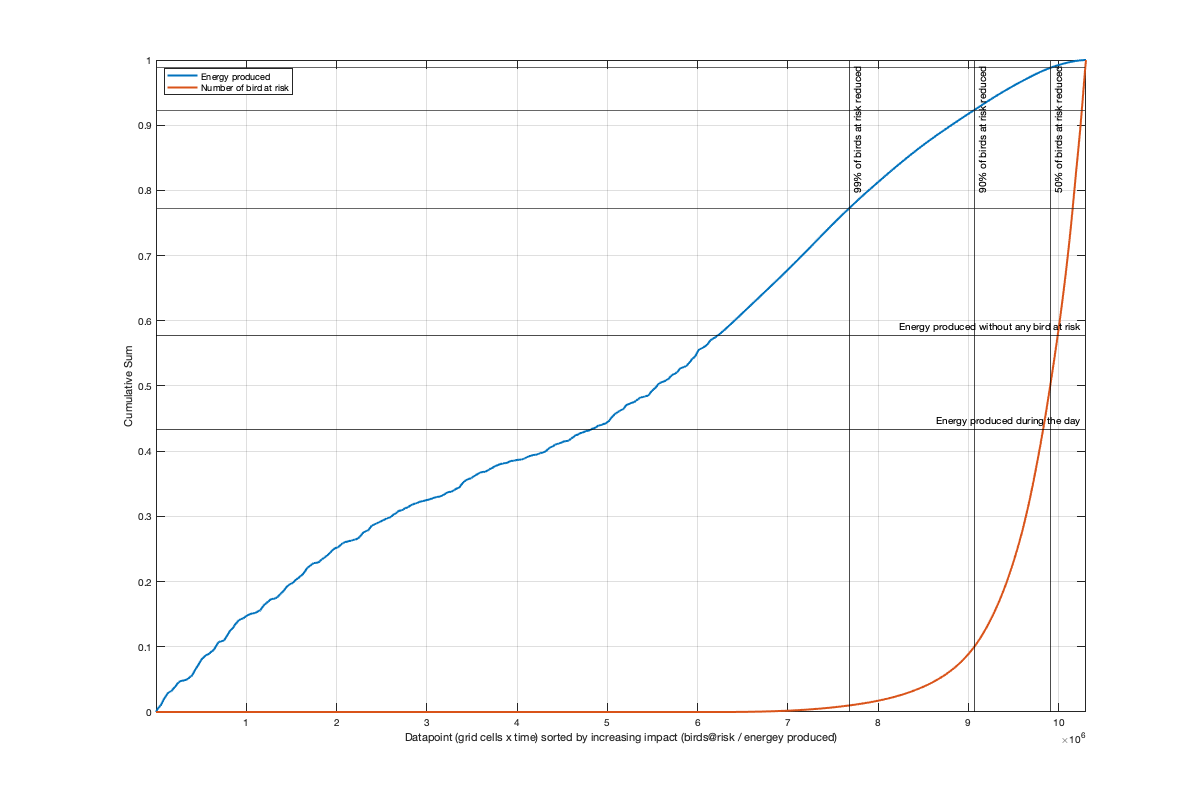

tmp = birdAtRisk(:)./energy(:);
[tmp_s,id] = sort(tmp);
id = id(~isnan(tmp_s));
figure('position',[0 0 1200 800]);  hold on; box on; grid on
% plot(tmp_s);
tmp_e = cumsum(energy(id),'omitnan')./nansum(energy(:));
plot(tmp_e,'linewidth',2)   
tmp_b = cumsum(birdAtRisk(id))./nansum(birdAtRisk(:));
plot(tmp_b,'linewidth',2)
yline(energy_day,'-k','Energy produced during the day')
yline(energy_safe,'-k','Energy produced without any bird at risk')
xline(find(tmp_b>.5,1),'-k','50% of birds at risk reduced')
yline(tmp_e(find(tmp_b>.5,1)))
xline(find(tmp_b>.1,1),'-k','90% of birds at risk reduced')
yline(tmp_e(find(tmp_b>.1,1)))
xline(find(tmp_b>.01,1),'-k','99% of birds at risk reduced')
yline(tmp_e(find(tmp_b>.01,1)))
axis tight;
legend('Energy produced','Number of bird at risk','Location','northwest')
ylabel('Cumulative Sum')
xlabel('Datapoint (grid cells x time) sorted by increasing impact (birds@risk / energey produced)')

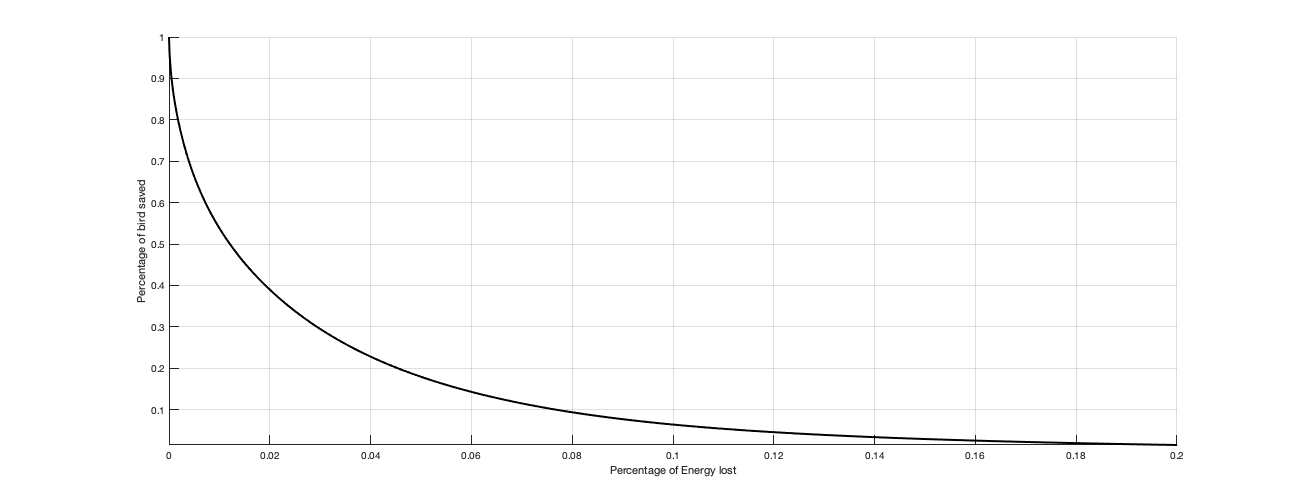

figure('position',[0 0 1300 500]);  hold on; grid on; 
plot((1-tmp_e),tmp_b,'k','linewidth',2);
axis tight; xlim([0 .2])
ylabel('Percentage of bird saved')
xlabel('Percentage of Energy lost')

## Scenario 2: Defined migration period

Daily

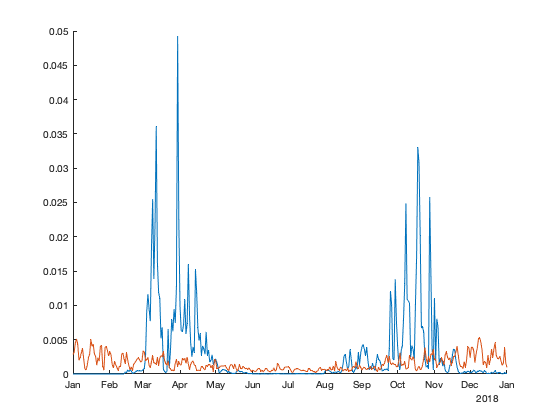

[G,t_day] = findgroups(dateshift(time,'start','day','nearest'));

tmp_b = splitapply( @sum, reshape(sum(sum(birdAtRisk),2),1,[]), G);
tmp_e = energy;
tmp_e(daynight)=0;
tmp_e = splitapply( @nansum, reshape(nansum(nansum(tmp_e),2),1,[]), G);

figure;
hold on
plot(t_day,tmp_b./sum(birdAtRisk(:)))
plot(t_day,tmp_e./nansum(energy(:)))

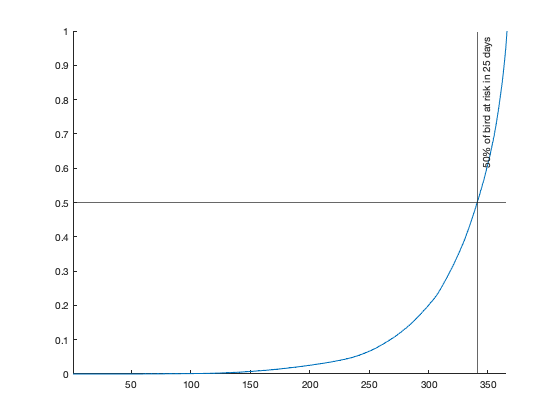


figure; hold on;
y=cumsum(sort(tmp_b))./sum(tmp_b);
plot(y)
yline(.5)
[~,tmp]=min(abs(y-.5));
xline(tmp,'-',['50% of bird at risk in ' num2str(numel(t_day)-tmp) ' days'])
axis tight;

Per block of week

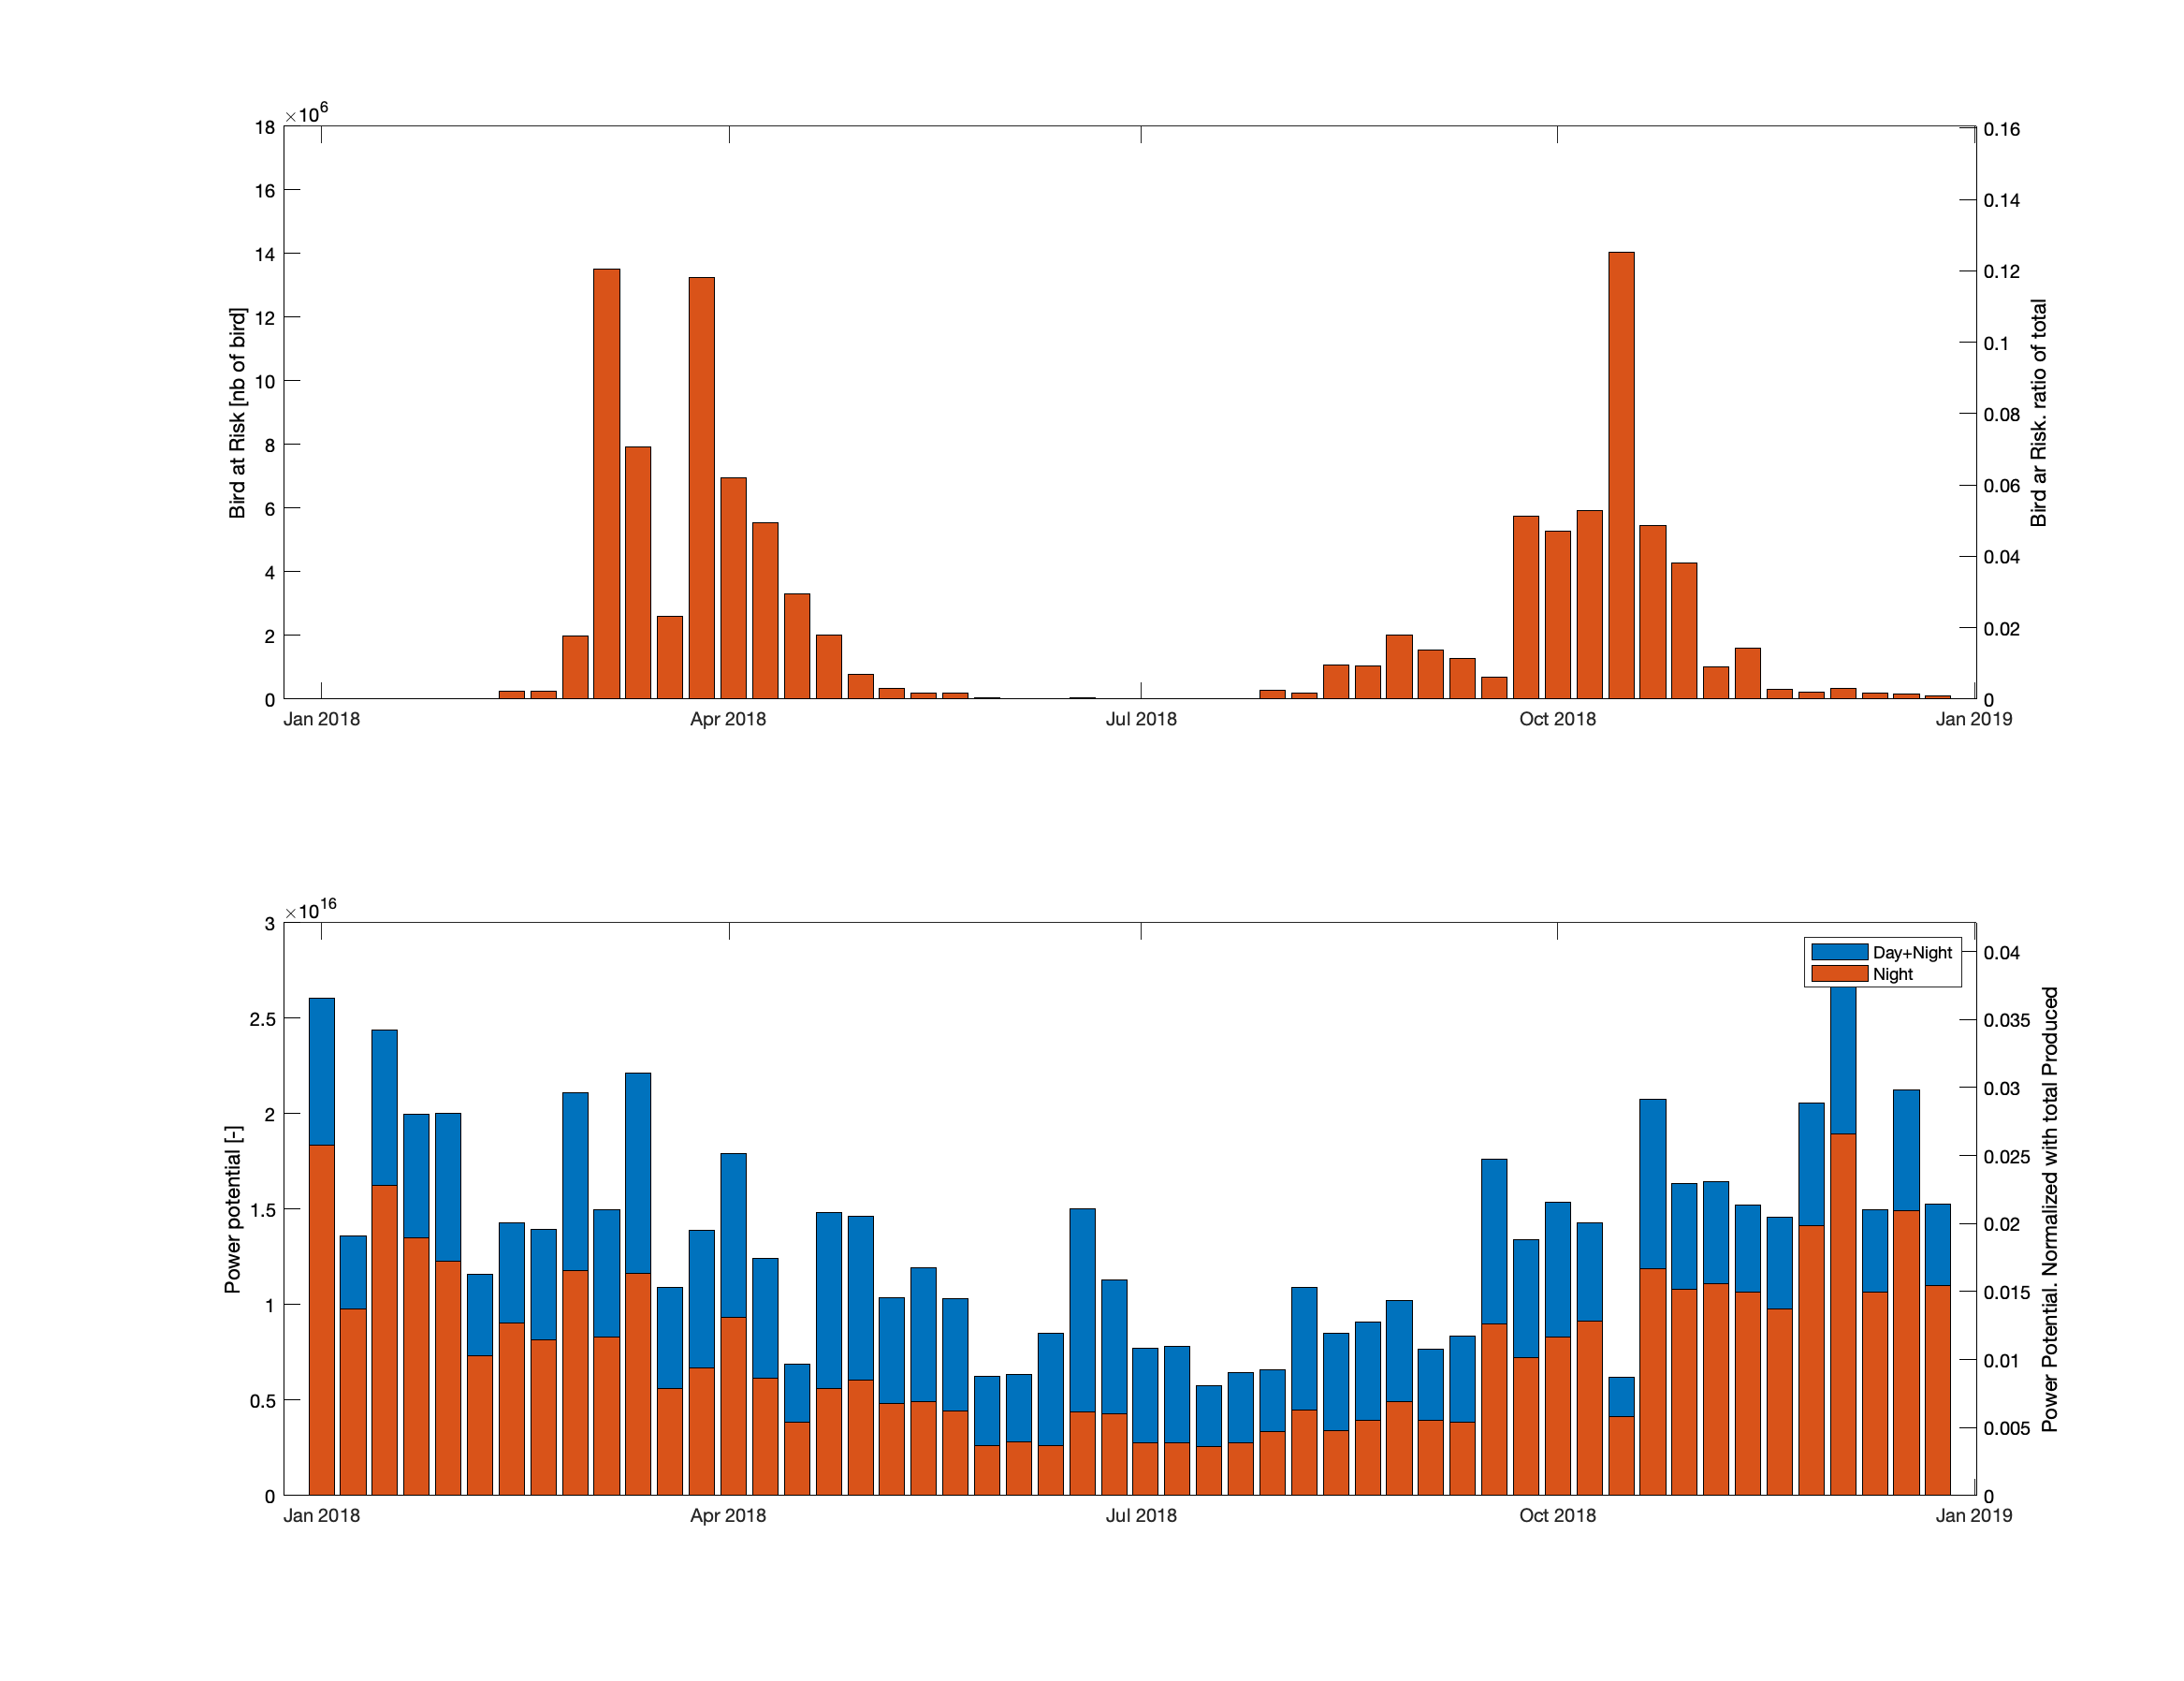

t_week = datetime('1-Jan-2018'):7:datetime('31-Dec-2018');

tmp_col = nan(4,numel(t_week)-1);
for i_t=1:numel(t_week)-1
    it = time>t_week(i_t)&time<t_week(i_t+1);
 
    tmp_b = birdAtRisk(:,:,it);
    tmp_n = ~daynight(:,:,it);
    tmp_e = energy(:,:,it);

    tmp_col(:,i_t) = [nansum(tmp_b(:)) nansum(tmp_b(tmp_n)) nansum(tmp_e(:)) nansum(tmp_e(tmp_n))];
end

figure('position',[0 0 1300 1000]); 
subplot(2,1,1); hold on;box on
bar(t_week(1:end-1),tmp_col(1,:))
bar(t_week(1:end-1),tmp_col(2,:))
ylim([0 18e6]); ylabel('Bird at Risk [nb of bird]')
yyaxis 'right'; ax = gca; ax.YAxis(2).Color = 'k'; box on
ylim([0 18e6]/sum(tmp_col(2,:))); ylabel('Bird ar Risk. ratio of total')

subplot(2,1,2); hold on; box on
bar(t_week(1:end-1),tmp_col(3,:))
bar(t_week(1:end-1),tmp_col(4,:))
ylim([0 3e16]); ylabel('Power potential [-]')
yyaxis 'right'; ax = gca; ax.YAxis(2).Color = 'k'; box on
ylim([0 3e16]/sum(tmp_col(3,:))); ylabel('Power Potential. Normalized with total Produced')
legend('Day+Night','Night');

Off certain Season

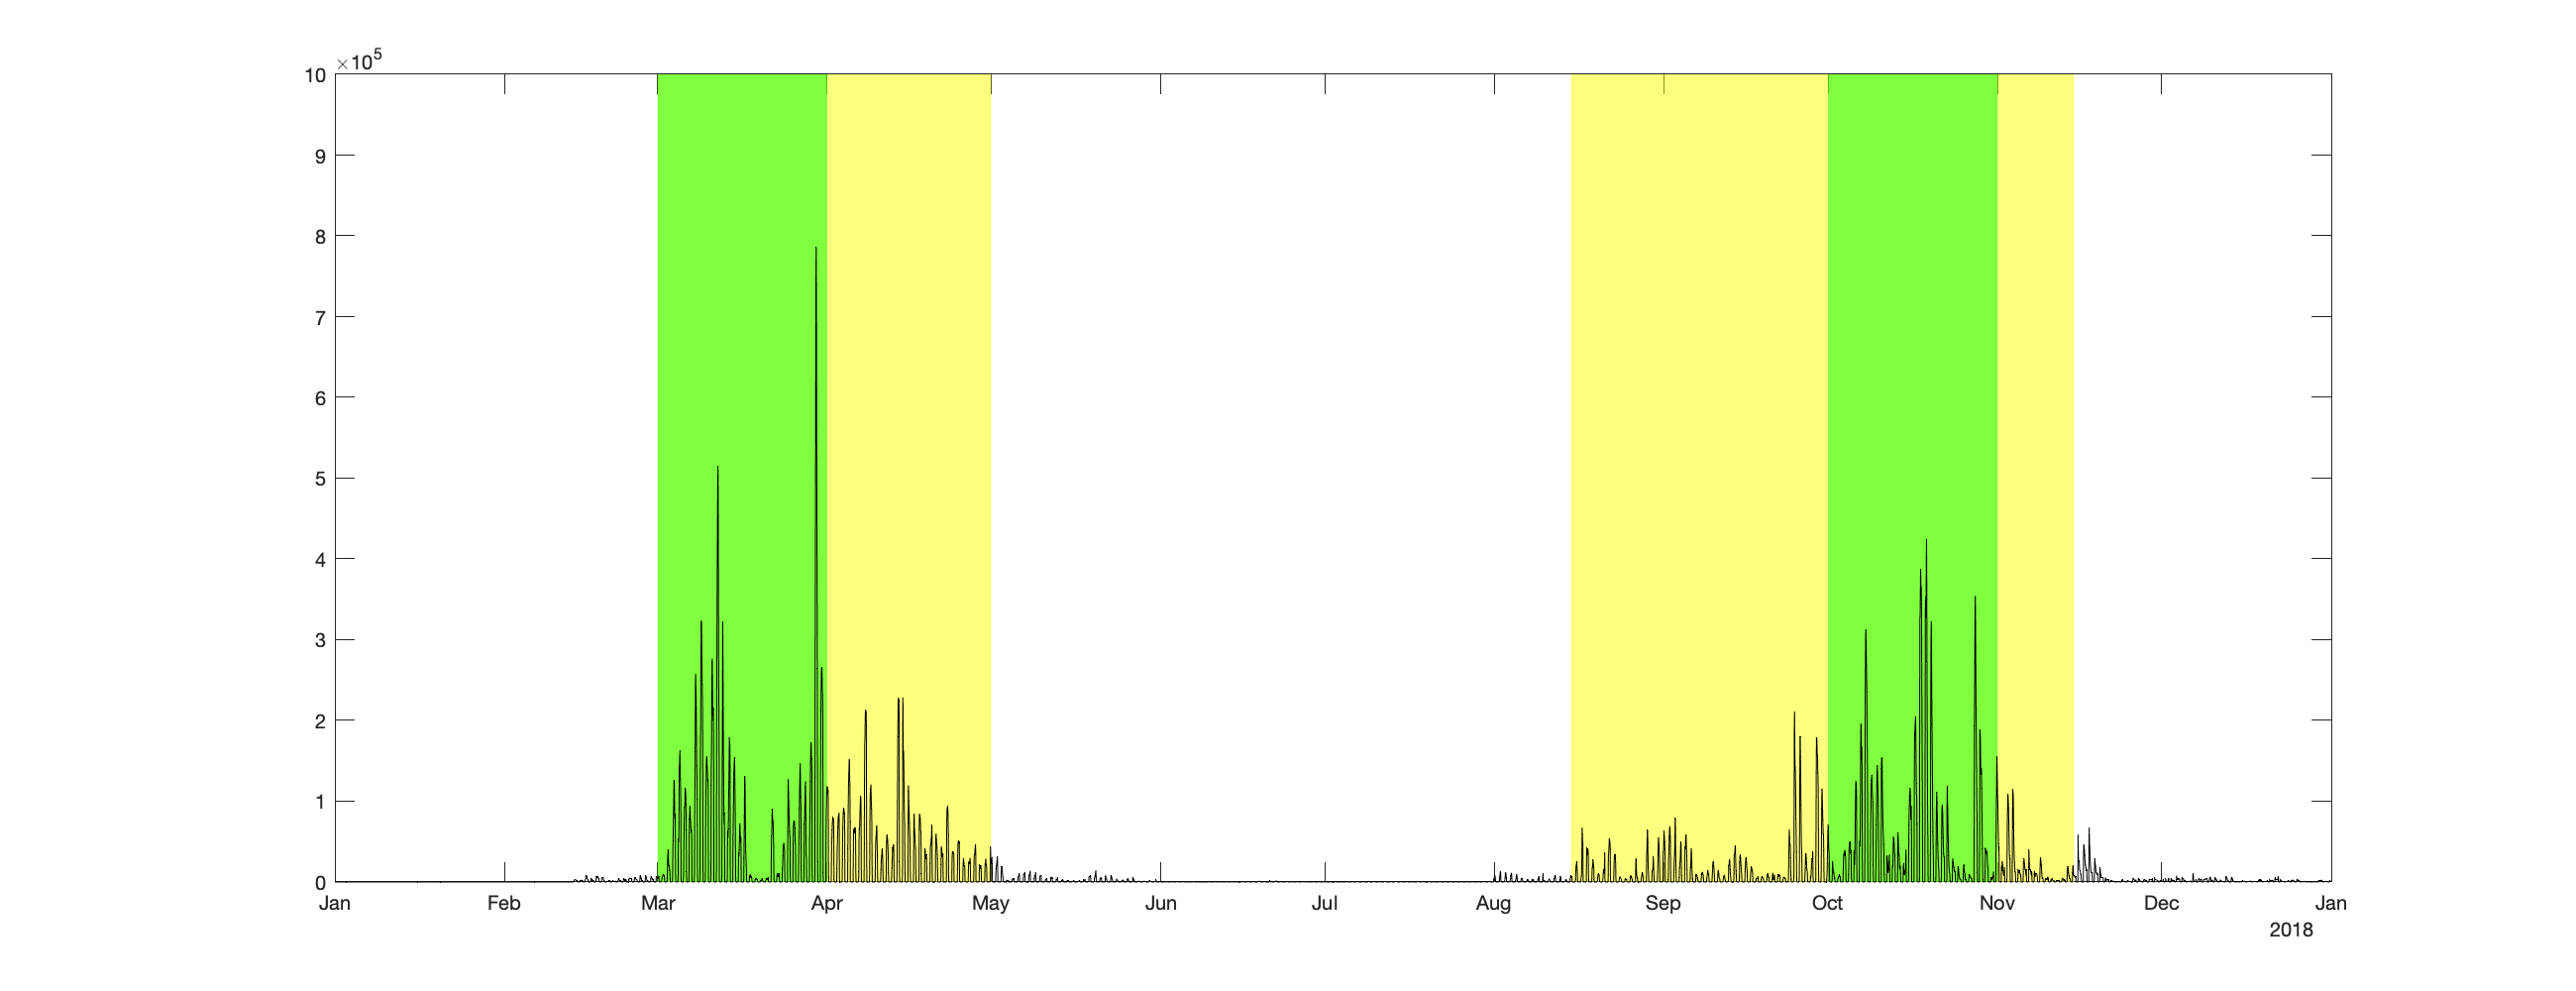

thr_date = datetime({...
    '1-Mar-2018','1-May-2018','15-Aug-2018','15-Nov-2018';...
    '1-Mar-2018','1-Apr-2018','1-Oct-2018','1-Nov-2018';...
    });

figure('position',[0 0 1300 500]); hold on
fill([thr_date(1,1) thr_date(1,2) thr_date(1,2) thr_date(1,1)],[0 0 10^6 10^6],'y','EdgeAlpha',0,'FaceAlpha',.5)
fill([thr_date(1,3) thr_date(1,4) thr_date(1,4) thr_date(1,3)],[0 0 10^6 10^6],'y','EdgeAlpha',0,'FaceAlpha',.5)
fill([thr_date(2,1) thr_date(2,2) thr_date(2,2) thr_date(2,1)],[0 0 10^6 10^6],'g','EdgeAlpha',0,'FaceAlpha',.5)
fill([thr_date(2,3) thr_date(2,4) thr_date(2,4) thr_date(2,3)],[0 0 10^6 10^6],'g','EdgeAlpha',0,'FaceAlpha',.5)
plot(time,reshape(sum(sum(birdAtRisk),2),1,[]),'k')
box on

clear tmp_col
tmp_col(1,:) = [nansum(birdAtRisk(:)) nansum(energy(:)) nansum(energy(:))];
for i_t=1:size(thr_date,1)
    it = ~( (time>thr_date(i_t,1)&time<thr_date(i_t,2)) | (time>thr_date(i_t,3)&time<thr_date(i_t,4)) );
    tmp_col(i_t+1,:) = [nansum(birdAtRisk(:,:,it),'all') nansum(energy(:,:,it),'all') nansum(energy(:,:,it),'all')+nansum(energy(:,:,~it).*daynight(:,:,~it),'all') ];
end
t=table({'No cut','yellow','green'}',tmp_col(:,1),tmp_col(:,2),tmp_col(:,3),'VariableNames',{'Mitigation','Bird at risk','Energy','Energy w/ Night'})

t = 3×4 table
    Mitigation    Bird at risk      Energy      Energy w/ Night
    __________    ____________    __________    _______________

    {'No cut'}     1.1412e+08     7.1863e+17      7.1863e+17   
    {'yellow'}     5.4284e+06     4.1937e+17      5.5642e+17   
    {'green' }     4.2221e+07      5.791e+17      6.3971e+17   


t{:,2:end}=t{:,2:end}./t{1,2:end}*100

t = 3×4 table
    Mitigation    Bird at risk    Energy    Energy w/ Night
    __________    ____________    ______    _______________

    {'No cut'}          100          100           100     
    {'yellow'}       4.7569       58.357        77.427     
    {'green' }       36.998       80.584        89.018     


Running windows of 1 and 2 weeks

Per day

time_d = dateshift(time,"start",'day');
birdAtRisk_d = splitapply(@sum, squeeze(sum(birdAtRisk,[1 2])),findgroups(time_d'));
energy_d = splitapply(@sum, squeeze(sum(energy,[1 2],'omitnan')),findgroups(time_d'));

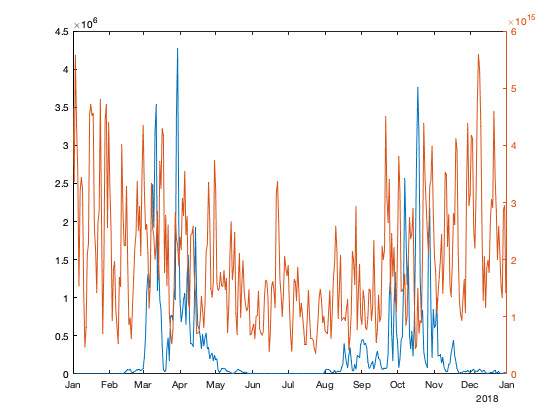

figure; hold on; box on
plot(unique(time_d),birdAtRisk_d)
yyaxis right; plot(unique(time_d),energy_d)

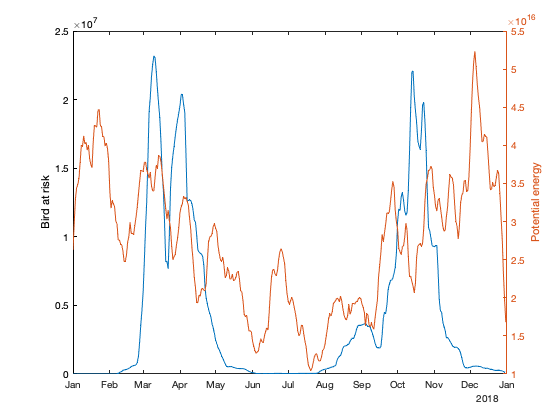

figure; 
plot(unique(time_d),movsum(birdAtRisk_d,14)); ylabel('Bird at risk')
yyaxis right; plot(unique(time_d),movsum(energy_d,14)); ylabel('Potential energy')

## Scenario 3: Map

Where are the bird at risk during the migration period?

it = ( (time>thr_date(1,1)&time<thr_date(1,2)) | (time>thr_date(1,3)&time<thr_date(1,4)) );
tmp_b = nansum(birdAtRisk(:,:,it),3);
tmp_e = energy(:,:,it);
tmp_n = ~daynight(:,:,it);
tmp_e(~tmp_n) = 0;
tmp_e = nansum(tmp_e,3);

load coastlines
dcoast = pdist2([g.lat2D(:) g.lon2D(:)],[coastlat coastlon], @lldistkm);
dcoast = reshape(min(dcoast,[],2),size(g.lat2D));

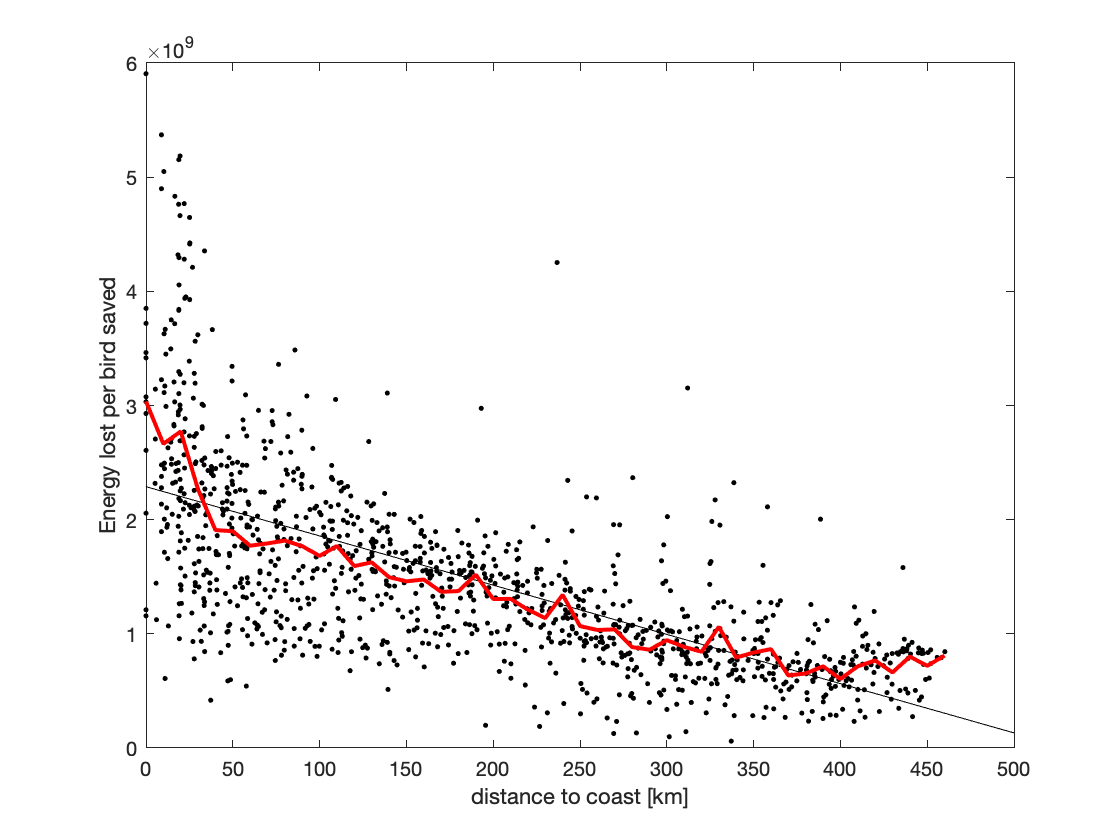

figure; hold on; box on;
plot(dcoast(:), tmp_e(:)./tmp_b(:),'.k'); lsline;
[G,dcoast_bin] = findgroups(round(dcoast(:),-1));
plot(dcoast_bin, splitapply(@nanmean,tmp_e(:)./tmp_b(:),G),'-r','linewidth',2)
xlabel('distance to coast [km]');
ylabel('Energy lost per bird saved')

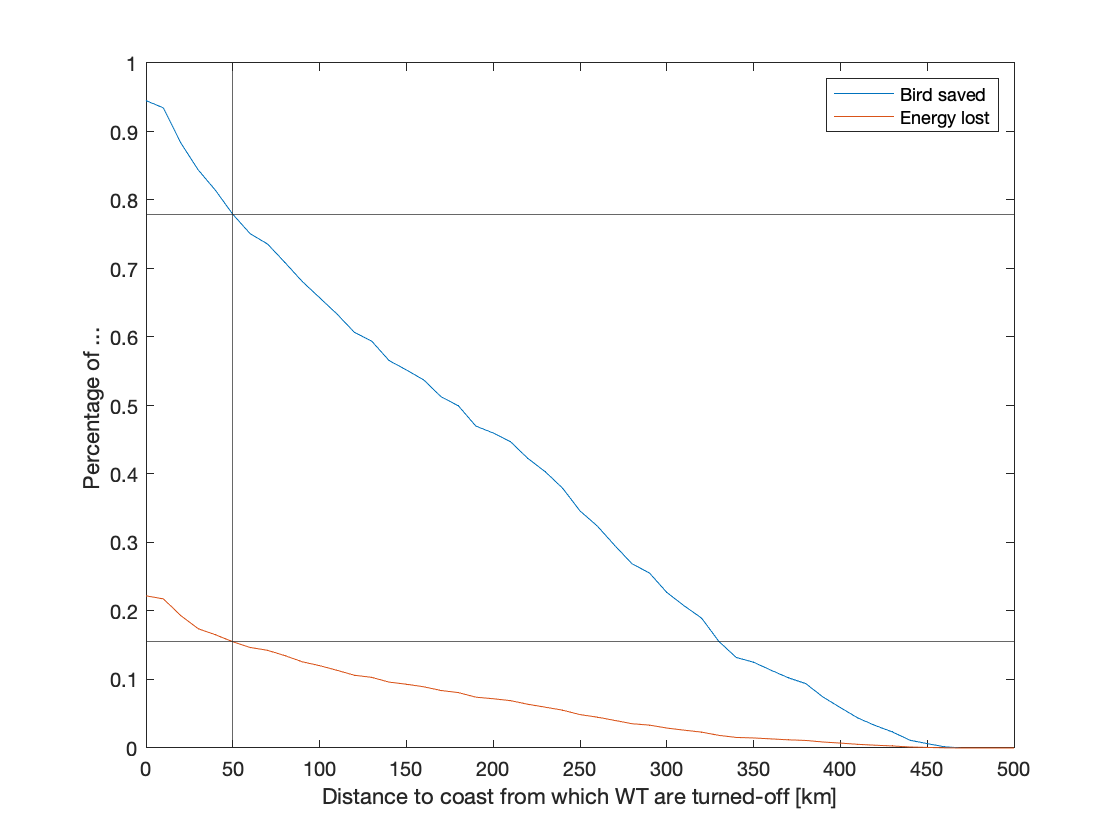

ddd=0:10:500;
tmp_bdd=nan(size(ddd)); tmp_edd=nan(size(ddd));
for i_d=1:numel(ddd)
    tmp_bdd(i_d)=nansum(tmp_b(dcoast>ddd(i_d)))/nansum(birdAtRisk(:));
    tmp_edd(i_d)=nansum(tmp_e(dcoast>ddd(i_d)))/nansum(energy(:));
end
figure; hold on; box on
plot(ddd,tmp_bdd)
plot(ddd,tmp_edd)
xline(50)
yline(tmp_bdd((ddd==50)))
yline(tmp_edd((ddd==50)))
xlabel('Distance to coast from which WT are turned-off [km]');
ylabel('Percentage of ... ')
legend('Bird saved','Energy lost')

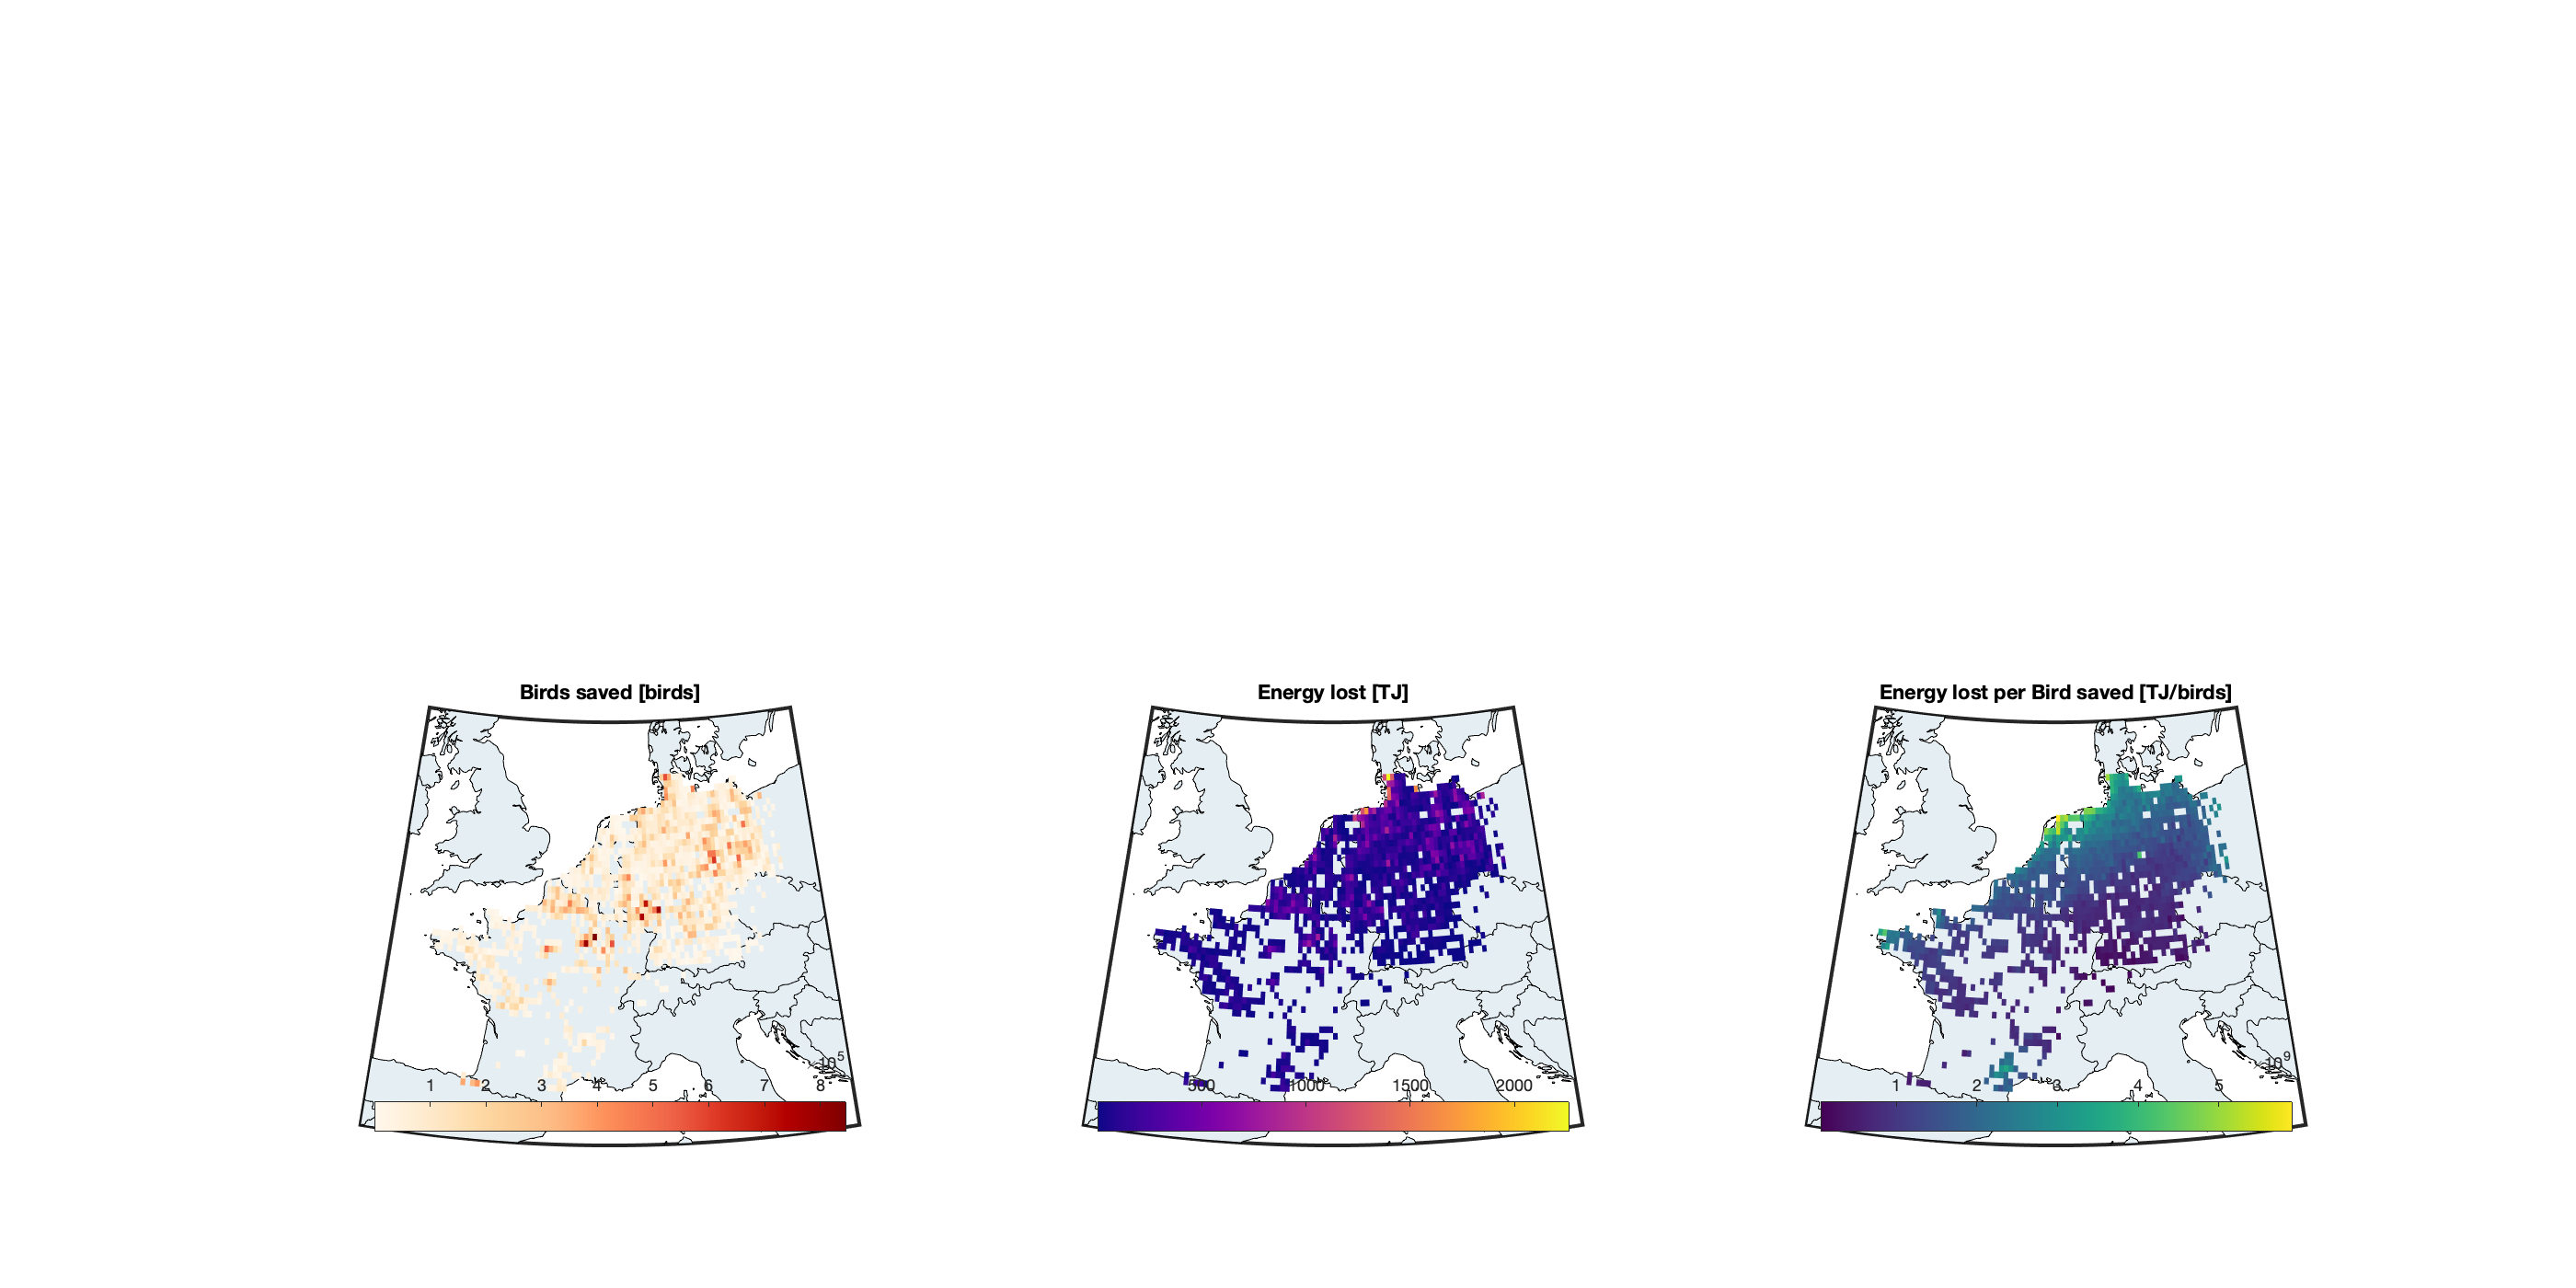

figure('position',[0 0 1400 700]); 

ax1=subplot(size(thr_date,1),3,(i_t-1)*3+1); hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
bordersm('countries','facecolor',[228 238 243]./255);
tmp = tmp_b;
tmp(tmp==0)=nan;
surfm(g.lat,g.lon,tmp)
c=colorbar('south'); title('Birds saved [birds]');
colormap(ax1,brewermap([],'OrRd'))
    
ax2=subplot(size(thr_date,1),3,(i_t-1)*3+2);  hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
bordersm('countries','facecolor',[228 238 243]./255);
tmp2 = tmp_e;
tmp2(tmp2==0)=nan;
surfm(g.lat,g.lon,tmp2/1e12)
%scatterm(tim.Latitude,tim.Longitude,'.k');
c=colorbar('south'); title('Energy lost [TJ]');
colormap(ax2,plasma)

ax3=subplot(size(thr_date,1),3,(i_t-1)*3+3); hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
bordersm('countries','facecolor',[228 238 243]./255);
surfm(g.lat,g.lon,tmp2./tmp)
%scatterm(tim.Latitude,tim.Longitude,'.k');
c=colorbar('south'); title('Energy lost per Bird saved [TJ/birds]');
colormap(ax3,viridis)

## Scenario 4: Wind direction

Select only during broad migration

i_t = 1;
it1 = time>thr_date(i_t,1)&time<thr_date(i_t,2);
it2 = time>thr_date(i_t,3)&time<thr_date(i_t,4);

Compute average birdflow direction (weighted by the flow)

% tmp = birdFlow(:,:,it1).*exp(1i*birdDir(:,:,it1));
% mid=nanmean(tmp(:));
% wdir_mean(1) = atan2(imag(mid),real(mid));
% tmp = birdFlow(:,:,it2).*exp(1i*birdDir(:,:,it2));
% mid=nanmean(tmp(:));
% wdir_mean(2) = atan2(imag(mid),real(mid));
% rad2deg(wdir_mean)

Instead, we simplify with,

wdir_mean = deg2rad([45 -135]);

Compute the angle difference between direction of wind and the 45/135°

d = abs(mod(wdir(:,:,it1)-wdir_mean(1)+pi, 2*pi) - pi);
diffit1 = abs(mod(wdir(:,:,it1)-wdir_mean(1)+pi, 2*pi) - pi);
diffit2 = abs(mod(wdir(:,:,it2)-wdir_mean(2)+pi, 2*pi) - pi);
diffit=cat(3,diffit1,diffit2);

Compute as a function of the threashold of angle

tmp_b = birdAtRisk(:,:,it1|it2);
tmp_e = energy(:,:,it1|it2);
tmp_n = ~daynight(:,:,it1|it2);
% only consider night time
tmp_e(~tmp_n) = 0;
dd=0:0.1:pi;
tmp_bdd=nan(size(dd)); tmp_edd=nan(size(dd));
for i_d=1:numel(dd)
    tmp_bdd(i_d) = nansum(tmp_b(diffit < dd(i_d)));
    tmp_edd(i_d) = nansum(tmp_e(diffit < dd(i_d)));
end

Illustrations

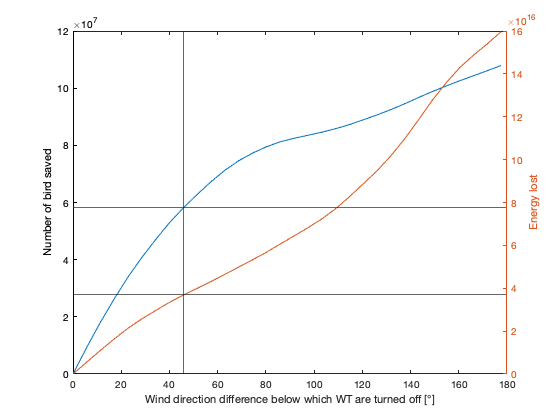

figure; hold on; box on
plot(rad2deg(dd),tmp_bdd); ylabel('Number of bird saved')
yline(tmp_bdd((dd==.8)))
yyaxis right; 
plot(rad2deg(dd),tmp_edd);ylabel('Energy lost')
xline(rad2deg(.8))
yline(tmp_edd((dd==.8)))
xlabel('Wind direction difference below which WT are turned off [°]');

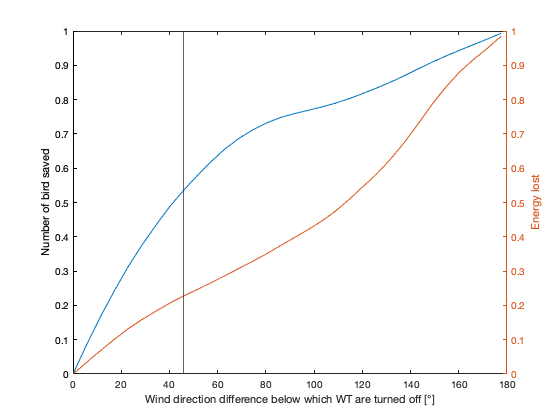

figure; hold on; box on
plot(rad2deg(dd),tmp_bdd./sum(tmp_b(:))); ylabel('Number of bird saved')
%yline(tmp_bdd((dd==.8)))
yyaxis right; 
plot(rad2deg(dd),tmp_edd./nansum(tmp_e(:)));ylabel('Energy lost')
xline(rad2deg(.8))
%yline(tmp_edd((dd==.8)))
xlabel('Wind direction difference below which WT are turned off [°]');

## Scenario: function of bird flow

Compute bird saved and energy lost for different threashold of bird flow (bird/m^2/hr)

birdf = logspace(-4,-2,100);
birdAtRisk_saved=nan(size(birdf));
energy_lost=nan(size(birdf));
for i_d=1:numel(birdf)
    id = birdFlow > birdf(i_d);
    birdAtRisk_saved(i_d) = sum(birdAtRisk(id));
    energy_lost(i_d) = sum(energy(id));
end

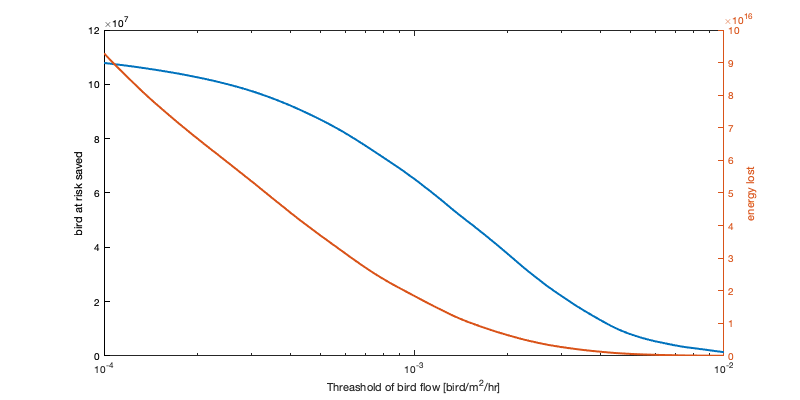

figure('position',[0 0 800 400]); box on; grid on
plot(birdf, birdAtRisk_saved,'linewidth',2); ylabel('bird at risk saved');
yyaxis right;
plot(birdf, energy_lost,'linewidth',2); ylabel('energy lost')
set(gca,'xscale','log')
xlabel('Threashold of bird flow [bird/m^2/hr]')